clear all;

% Classroom demo: Fourier and sampling accuracy.

% PARAMETERS

dt       = 0.01;  % Demo 1: 0.01

lambda1  = 1.0;
lambda2  = 1./ 1.35;   %Demo 1 
lambda3  = 1.0  / 2.2; %Demo 1

%lambda2  = 1./ 0.90;   %Demo 2 
%lambda3  = 1.0  / 1.1; %Demo 2

amp1     = 1.0;
amp2     = 1.5;
amp3     = 2.0;

signallength  = 1000;    

xrange_max    = 10;
xrange_max_nu = 3;

%----------------------


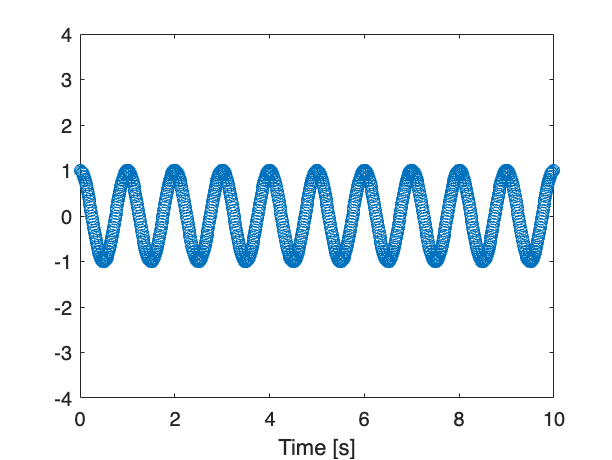

% Create some waves

t  = 0:dt:signallength-dt;   % in "seconds"

y1 = amp1 * cos( 2*pi*t / lambda1);
y2 = amp2 * sin( 2*pi*t / lambda2);
y3 = amp3 * cos( 2*pi*t / lambda3);

%plot(t, y1, 'Color', 'blue', 'LineWidth', 2);
plot(t, y1, 'o');
xlabel('Time [s]')
ylim([-4, 4])
xlim([0, xrange_max])

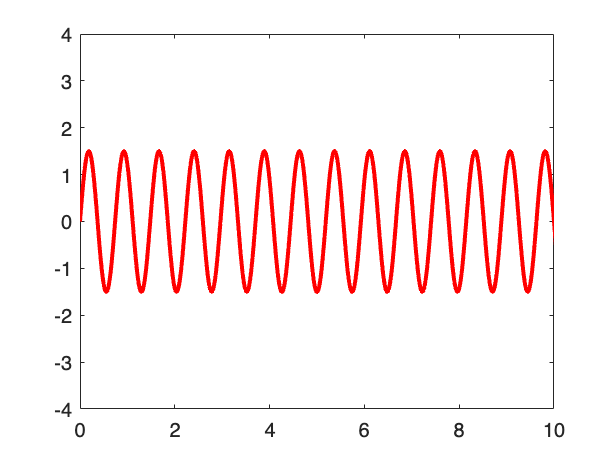

%hold
plot(t, y2, 'Color', 'red', 'LineWidth', 2);
ylim([-4, 4])
xlim([0, xrange_max])

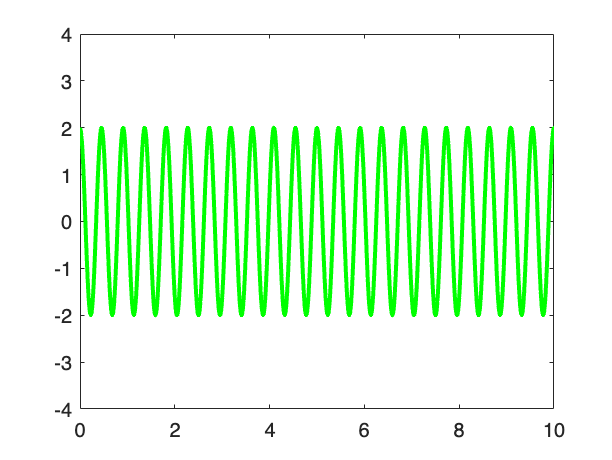

plot(t, y3, 'Color', 'green', 'LineWidth', 2);
ylim([-4, 4])
xlim([0, xrange_max])

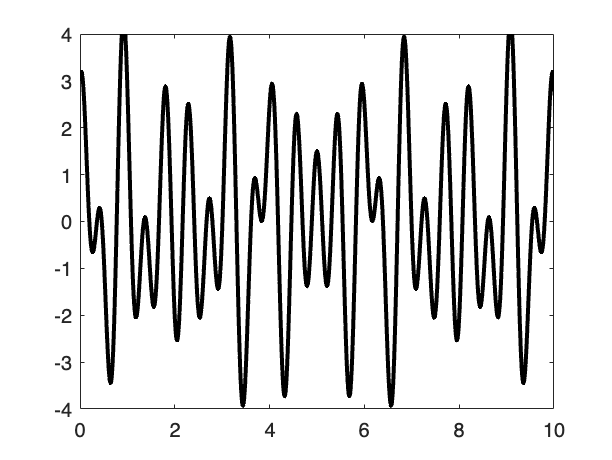


plot(t, y1 + y2 + y3, 'LineWidth',2, 'Color','Black');
%hold
ylim([-4, 4])
xlim([0, xrange_max])

% The frequencies corresponding to x:

samplingfreq = 1 ./ dt; 
Nsamples     = numel(t);

f = (0:Nsamples-1) * (1 / (dt * Nsamples) );

% Fourier spectrum

F_y1 = fft(y1);
F_y2 = fft(y2);
F_y3 = fft(y3);

F_y1_mag = abs( fftshift(F_y1) );
F_y2_mag = abs( fftshift(F_y2) );
F_y3_mag = abs( fftshift(F_y3) );

F_y1_mag = abs( F_y1 );
F_y2_mag = abs( F_y2 );
F_y3_mag = abs( F_y3 );

plot(f, F_y1_mag, 'Color', 'blue'   , 'LineWidth', 2)
xlabel('Frequency [Hz]')
xlim([0, xrange_max_nu])
%xlim([0.75, 1.5])
hold

Current plot held


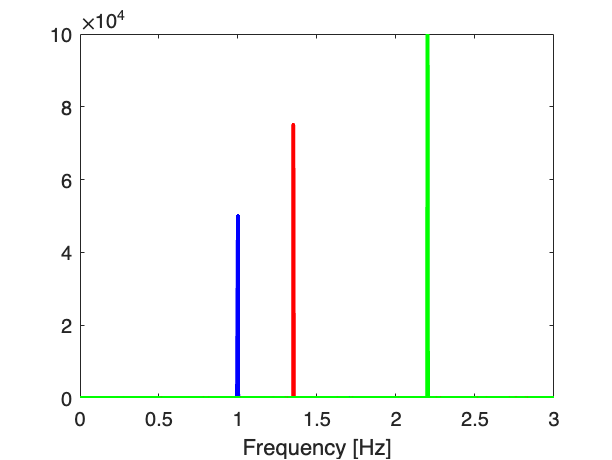

Current plot released


plot(f, F_y2_mag, 'Color', 'red'   , 'LineWidth', 2)
plot(f, F_y3_mag, 'Color', 'green', 'LineWidth', 2)
hold